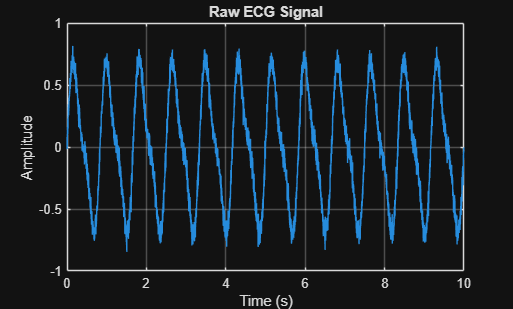

% ECG Signal Processing and Arrhythmia Detection
clc; clear; close all;

% Load ECG data
load('C:\matlap projects\6\ecg_signal.mat');  % Contains 'ecg_signal'
fs = 360;                % Sampling frequency
t = (0:length(ecg_signal)-1)/fs;

% Plot raw ECG signal
figure;
plot(t, ecg_signal);
title('Raw ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

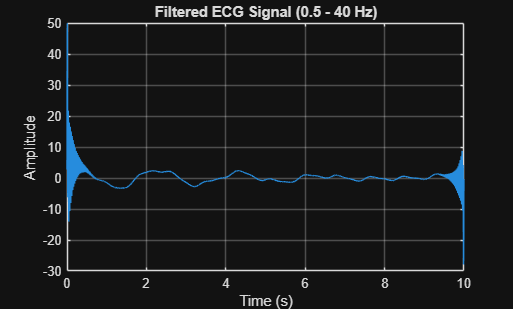


% ----------------------------
% Step 1: Bandpass Filtering
% ----------------------------
ecg_filtered = bandpass(ecg_signal, [0.5 40], fs);

figure;
plot(t, ecg_filtered);
title('Filtered ECG Signal (0.5 - 40 Hz)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

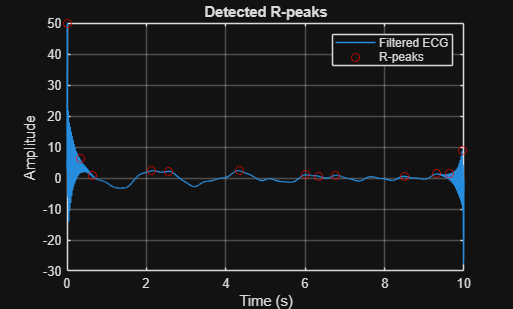


% ----------------------------
% Step 2: R-Peak Detection
% ----------------------------
[~, locs_Rwave] = findpeaks(ecg_filtered, ...
    'MinPeakHeight', 0.5, ...
    'MinPeakDistance', round(0.3 * fs));  % ~200 bpm max

% Plot R-peaks on signal
figure;
plot(t, ecg_filtered); hold on;
plot(t(locs_Rwave), ecg_filtered(locs_Rwave), 'ro');
title('Detected R-peaks');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Filtered ECG', 'R-peaks');
grid on;


% ----------------------------
% Step 3: Heart Rate Calculation
% ----------------------------
RR_intervals = diff(locs_Rwave) / fs;     % in seconds
BPM = 60 ./ RR_intervals;                 % Convert to BPM
avg_BPM = mean(BPM);

fprintf('Average Heart Rate: %.2f BPM\n', avg_BPM);

Average Heart Rate: 119.61 BPM



% ----------------------------
% Step 4: Arrhythmia Detection (Rule-Based)
% ----------------------------
% Threshold: BPM < 50 (bradycardia) or > 100 (tachycardia)
arrhythmia_index = find(BPM > 100 | BPM < 50);
fprintf('Detected %d arrhythmic beats.\n', length(arrhythmia_index));

Detected 11 arrhythmic beats.


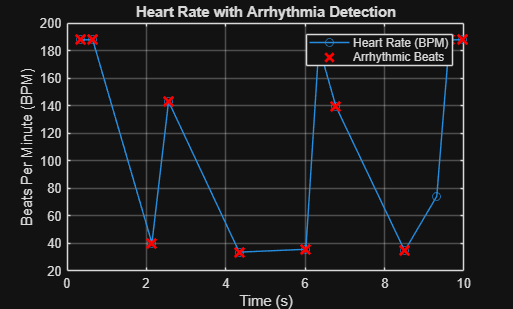


% ----------------------------
% Step 5: Plot BPM and Arrhythmia Points
% ----------------------------
time_bpm = t(locs_Rwave(2:end));  % Time of each BPM value

figure;
plot(time_bpm, BPM, '-o'); hold on;
plot(time_bpm(arrhythmia_index), BPM(arrhythmia_index), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Beats Per Minute (BPM)');
title('Heart Rate with Arrhythmia Detection');
legend('Heart Rate (BPM)', 'Arrhythmic Beats');
grid on;